# Assignment 6

## Question 1

tire = imread('tire.tif')

tire = 205×232 uint8 matrix
    6   14   10   10    4    3    2    2    1    1    3    4    3    2    2    1    1    0    2    3    2    6    5    2    4    1    1    1    4    3    1    3    2    2    1    0    1    1    4    4    0    1    1    1    2    1    1    1    1    1
   11   16   17   20    6    3    4    4    2    3    5   10    7    1    2    2    1    2    1    1    1    5    5    3    4    2    2    2    3    2    2    3    2    2    1    2    3    2    6    7    1    1    2    3    2    2    2    1    2    4
   11   20   15   10    5    4    4    3    6    7    7    5    2    1    1    2    3    3    2    2    4    0    2    3    2    4    5    4    3    2    3    1    1    2    2    2    3    2    2    2    2    2    2    2    2    2    2    2    1    6
   13   16    6    2    2    2    2    9   11    7    1    1    2    2    4    4    2    2    3    4    3    2    5    2    2    1    6   10    2    2    3    3    1    1    2    1    2    1    3    2    1    1    1    

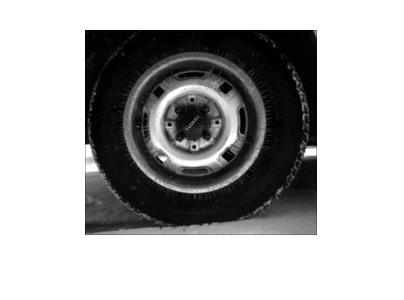

imshow(tire)

ans = 85

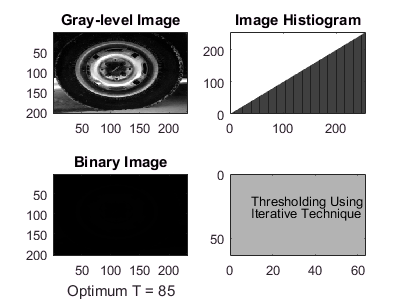


rd(tire)

## Question 2

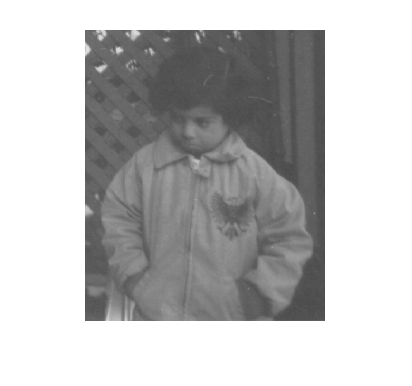

q2_im = imread('pout.tif');

figure()
imshow(q2_im);

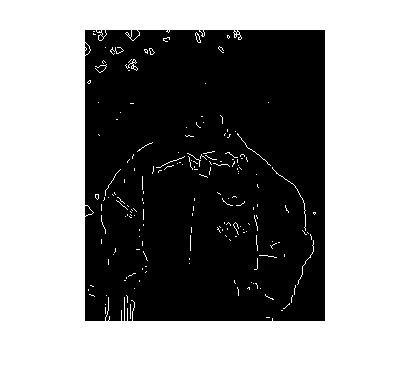

q2_sobel = edge(q2_im, 'sobel');
q2_canny = edge(q2_im, 'Canny');
imshow(q2_sobel);

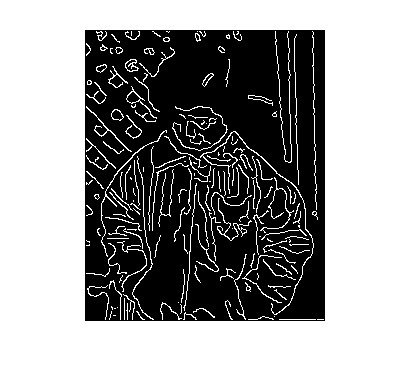

imshow(q2_canny);

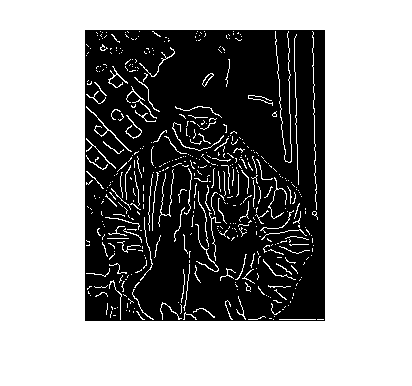

imshow(q2_canny - q2_sobel);

## Question 3

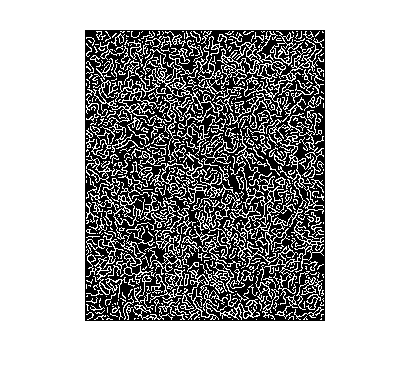

q3_noise_gaussian = imnoise(q2_im,'gaussian',0,0.10);
q3_noise_sandp = imnoise(q2_im,'salt & pepper',0.5);
q3_noise_speckle = imnoise(q2_im,'speckle',0.10);

imshow(edge(q3_noise_gaussian, 'Canny') - edge(q3_noise_gaussian, 'sobel'));

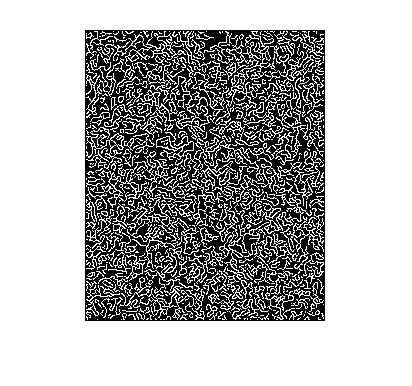

imshow(edge(q3_noise_sandp, 'Canny') - edge(q3_noise_sandp, 'sobel'));

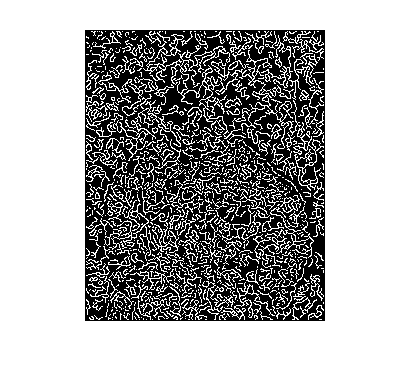

imshow(edge(q3_noise_speckle, 'Canny') - edge(q3_noise_speckle, 'sobel'));

## Question 4

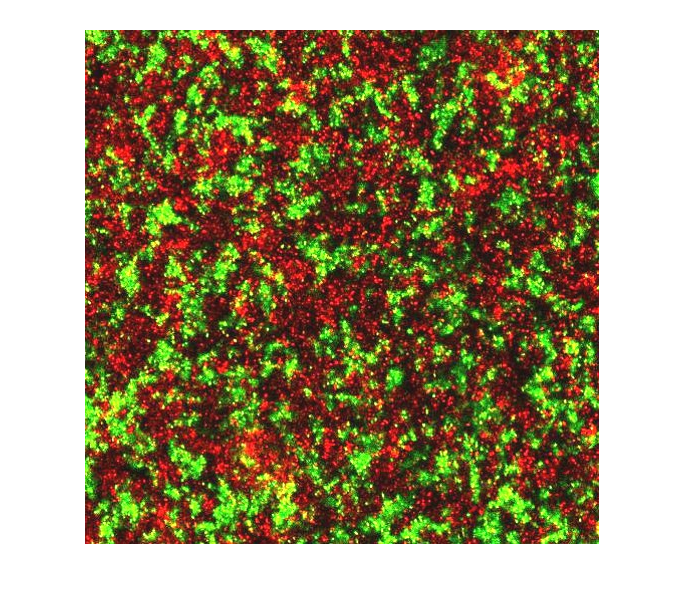

q4_im = imread('Ecoli.jpg');
imshow(q4_im);

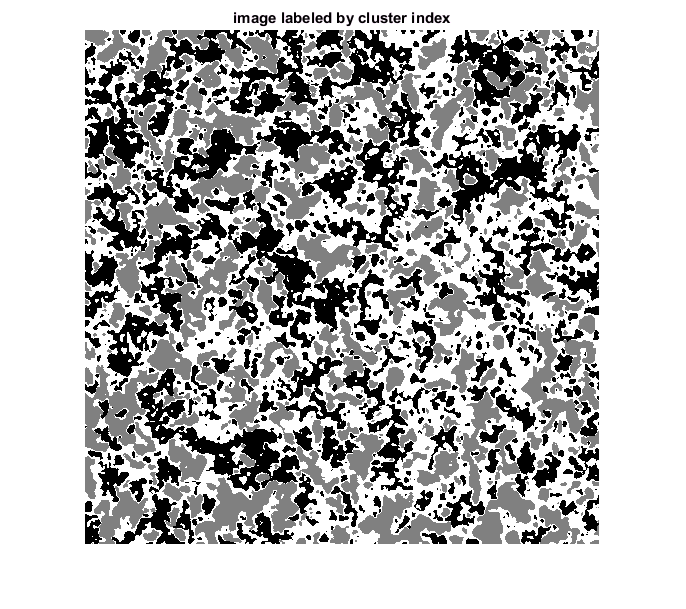

q4_cform = makecform('srgb2lab');
q4_cim = applycform(q4_im,q4_cform);

q4_ab = double(q4_cim(:,:,2:3));
nrows = size(q4_ab,1);
ncols = size(q4_ab,2);
q4_ab = reshape(q4_ab,nrows*ncols,2);

q4_nColors = 3;
% repeat the clustering 3 times to avoid local minima
[cluster_idx, cluster_center] = kmeans(q4_ab,q4_nColors,'distance','sqEuclidean', 'Replicates',3);

pixel_labels = reshape(cluster_idx,nrows,ncols);

imshow(pixel_labels,[]), title('image labeled by cluster index');

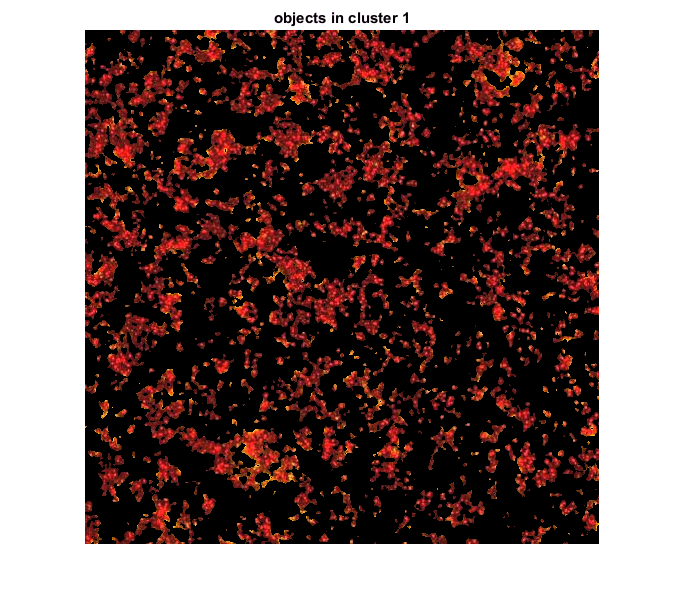

segmented_images = cell(1,3);
rgb_label = repmat(pixel_labels,[1 1 3]);

for k = 1:q4_nColors
    color = q4_im;
    color(rgb_label ~= k) = 0;
    segmented_images{k} = color;
end

imshow(segmented_images{1}), title('objects in cluster 1');

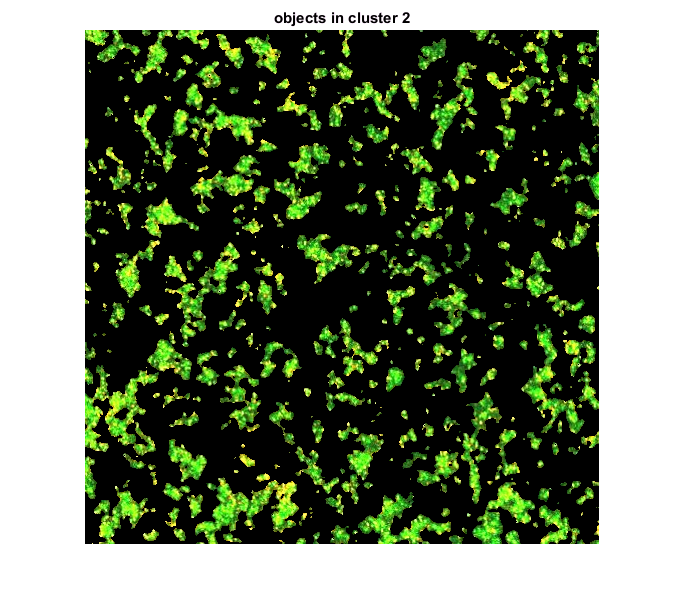

imshow(segmented_images{2}), title('objects in cluster 2');

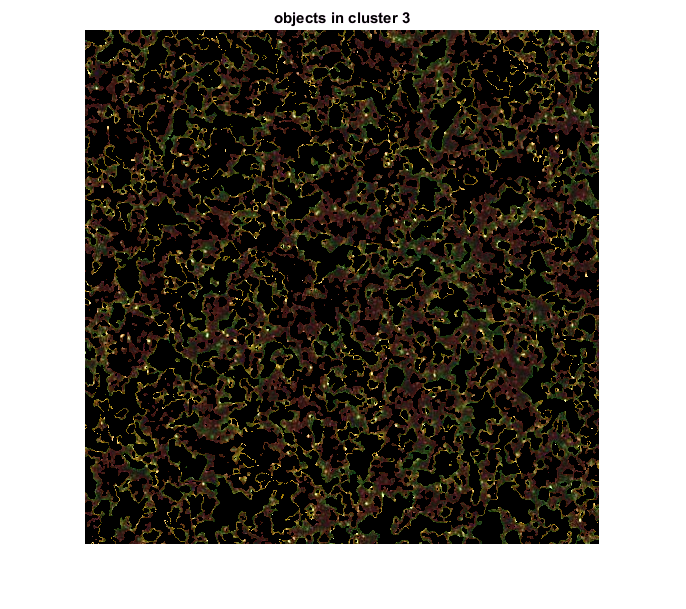

imshow(segmented_images{3}), title('objects in cluster 3');

## Question 5

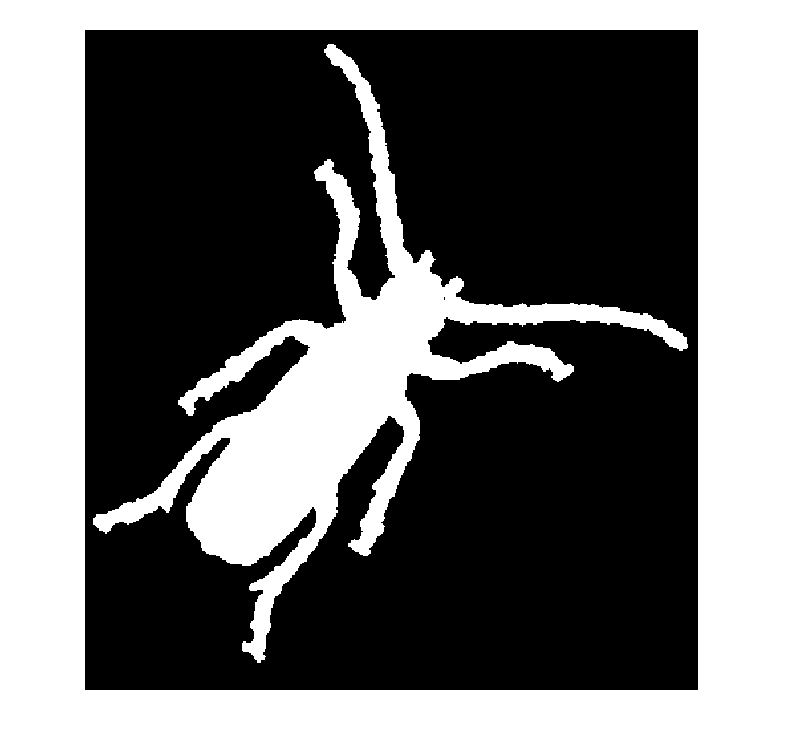

q5_im = imread('beetle.gif');
imshow(q5_im);

% PART A
q5_M00 = raw_moments(q5_im, 0, 0)

Error using  .* 
Integers can only be combined with integers of the same class, or scalar doubles.

Error in assignment6_1>raw_moments (line 98)
    outmom = sum(sum( double( uint32((1:(size(img,1)))'.^j * (1:(size(img,2))).^i) .* double(img) ) ));

q5_M01 = raw_moments(q5_im, 0, 1)
q5_M10 = raw_moments(q5_im, 1, 0)
q5_M11 = raw_moments(q5_im, 1, 1)
q5_M02 = raw_moments(q5_im, 0, 2)
q5_M20 = raw_moments(q5_im, 2, 0)
q5_M22 = raw_moments(q5_im, 2, 2)

% PART B
q5_M00_2 = raw_moments2(q5_im, 0, 0)
q5_M01_2 = raw_moments2(q5_im, 0, 1)
q5_M10_2 = raw_moments2(q5_im, 1, 0)
q5_M11_2 = raw_moments2(q5_im, 1, 1)
q5_M02_2 = raw_moments2(q5_im, 0, 2)
q5_M20_2 = raw_moments2(q5_im, 2, 0)
q5_M22_2 = raw_moments2(q5_im, 2, 2)

% PART C
q5_orientation = ((1/2)*(atan((2*q5_M11)/(q5_M20-q5_M02))))
q5_orientation2 = ((1/2)*(atan((2*q5_M11_2)/(q5_M20_2-q5_M02_2))))

## Question 6

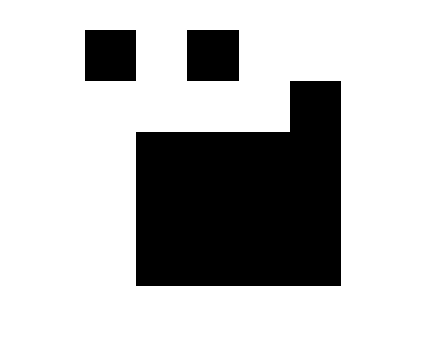

q6_arr = [0 1 0 1 1; 1 1 1 1 0; 1 0 0 0 0; 1 0 0 0 0; 1 0 0 0 0];
imshow(imresize(q6_arr, [256 256], 'box'));


q6_M00 = raw_moments(q6_arr, 0, 0)

q6_M00 = 15475950

q6_M01 = raw_moments(q6_arr, 0, 1)

q6_M01 = 5.6361e+09

q6_M10 = raw_moments(q6_arr, 1, 0)

q6_M10 = 3.9627e+09

q6_M11 = raw_moments(q6_arr, 1, 1)

q6_M11 = 1.3552e+12

q6_M02 = raw_moments(q6_arr, 0, 2)

q6_M02 = 2.2423e+12

q6_M20 = raw_moments(q6_arr, 2, 0)

q6_M20 = 1.1721e+12

q6_M22 = raw_moments(q6_arr, 2, 2)

q6_M22 = 2.6065e+14


% PART B
q6_M00_2 = raw_moments2(q6_arr, 0, 0)

q6_M00_2 = 15475950

q6_M01_2 = raw_moments2(q6_arr, 0, 1)

q6_M01_2 = 2.8180e+09

q6_M10_2 = raw_moments2(q6_arr, 1, 0)

q6_M10_2 = 1.9814e+09

q6_M11_2 = raw_moments2(q6_arr, 1, 1)

q6_M11_2 = 3.3880e+11

q6_M02_2 = raw_moments2(q6_arr, 0, 2)

q6_M02_2 = 5.6057e+11

q6_M20_2 = raw_moments2(q6_arr, 2, 0)

q6_M20_2 = 2.9303e+11

q6_M22_2 = raw_moments2(q6_arr, 2, 2)

q6_M22_2 = 8.4497e+15


% PART C
q6_orientation = ((1/2)*(atan((2*q6_M11)/(q6_M20-q6_M02))))

q6_orientation = -0.5974

q6_orientation2 = ((1/2)*(atan((2*q6_M11_2)/(q6_M20_2-q6_M02_2))))

q6_orientation2 = -0.5974

function outmom = raw_moments(im,i,j)
    img = double(im);
    outmom = sum(sum( ((1:size(img,1))'.^j * (1:size(img,2)).^i) .* img ));
end

function outmom = raw_moments2(im,i,j)
    img = double(im);
    outmom = sum(sum( (((1:size(img,1))'./2).^j * ((1:size(img,2))./2).^i) .* img ));
end